# Classification using mathematical expressions

Explore the world of classification:

- Begin with a straight line dividing a plane into two distinct regions.

- Delve into the Gaussian kernel, a complex yet powerful classification tool.

- Unravel the intricacies of neural networks, which create sophisticated classification boundaries.

## Linear equations

### Create an expression for a straight line

syms a b x y 
expr = a*x +b*y 

$$expr = a\,x+b\,y$$

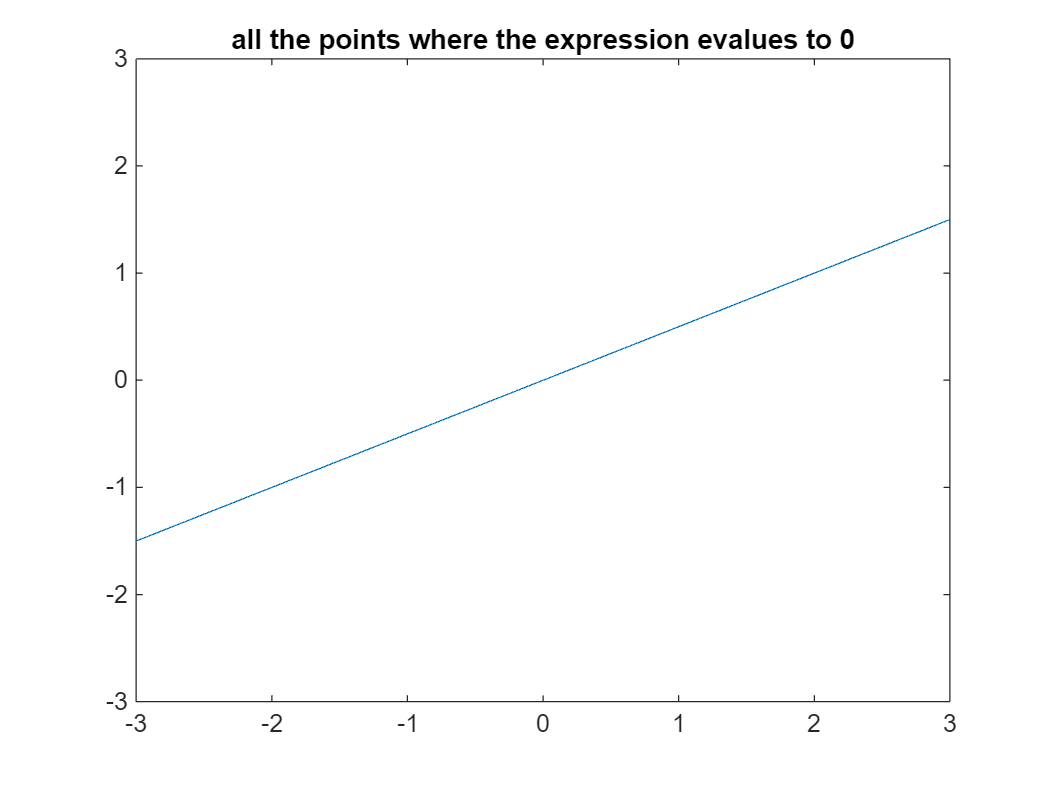

aValue = 1; bValue=-2; 
exprSpecific = subs(expr,[a,b],[aValue, bValue]);
figure()
fimplicit(exprSpecific==0, [-3,3])
title('all the points where the expression evalues to 0')

### Evaluate sample points from the plane using the expression

Sample the region and see how the implicit equation evaluates on these points 

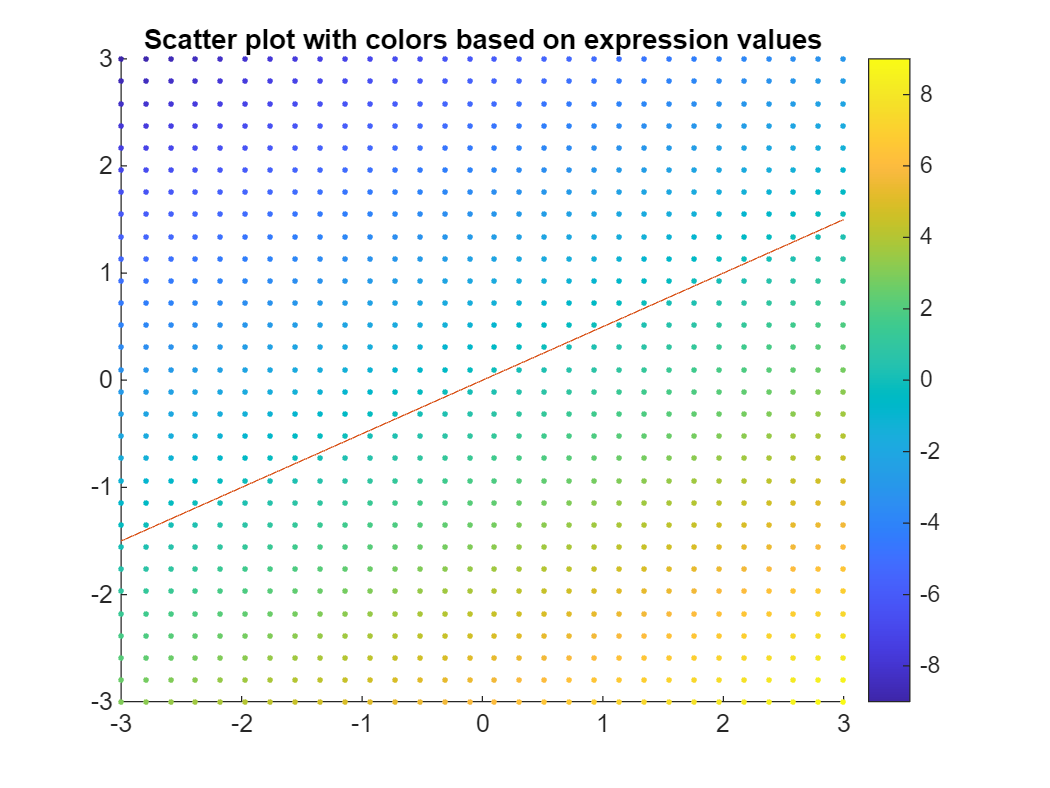

N = 30;
[X, Y] = meshgrid(linspace(-3, 3, N), linspace(-3, 3, N));
X = X(:); Y=Y(:);

LHS_values = double(subs(exprSpecific, {x, y}, {X, Y}));

%plotting 
scatterUsingValues(X,Y,LHS_values); 
hold on 
fimplicit(exprSpecific==0,[-3,3])
hold off

### Binary classification using thresholding

Let's plot binary colors based on positive or negative values 

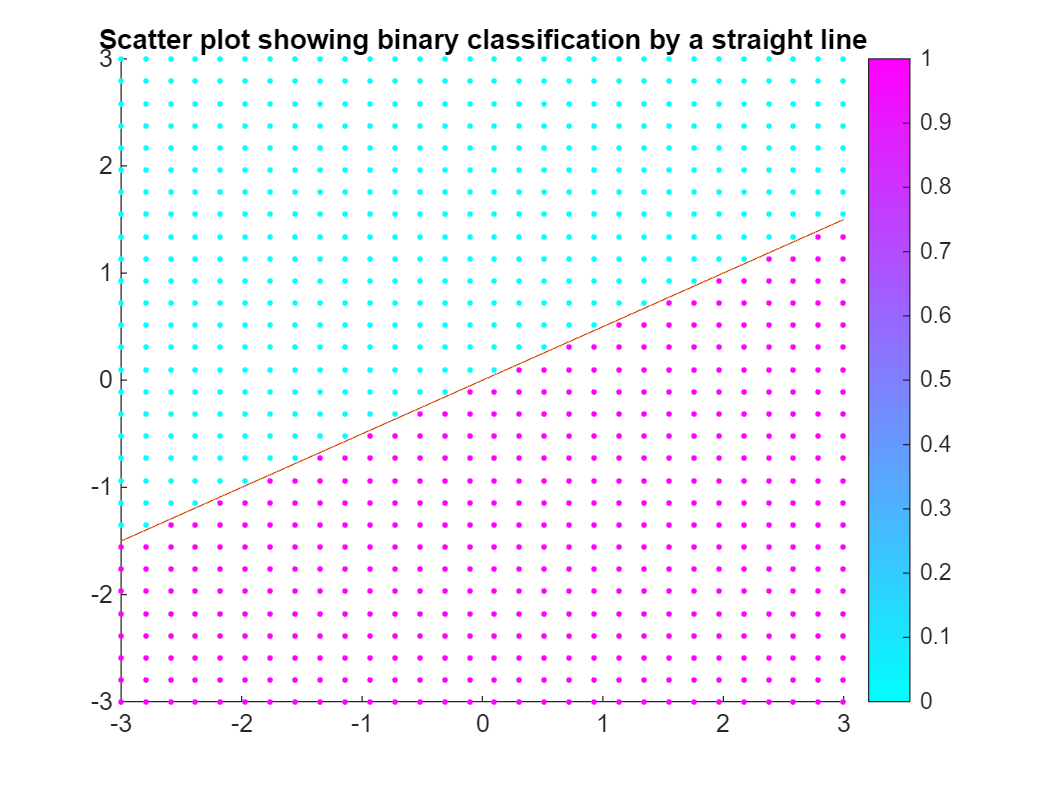

% Separate points based on the sign of the LHS values
binaryValues = zeros(size(LHS_values)); 
binaryValues(LHS_values>=0) = 1; 


%plotting 

scatterUsingValues(X,Y,binaryValues); 
colormap("cool")
hold on 
fimplicit(exprSpecific==0,[-3,3])
hold off
title('Scatter plot showing binary classification by a straight line')

Based on the above result, we can use the left hand side of the equation of a straight line for binary classification. 

- If we subsittue a point in the space into the experssion, we will say "Class A" if it evaluates to positive and "Class B" otherwise. 

## Non-linear equations

Can we only use linear equations? How about nonlinear ones? 

syms x y sigma mu
G = exp(-((x - mu)^2 + (y - mu)^2) / (2 * sigma^2))

$$G = {\mathrm{e}}^{-\frac{{\left(\mu -x\right)}^{2}+{\left(\mu -y\right)}^{2}}{2\,\sigma^{2}}}$$

The above expression is called a Gaussian radial basis function (RBF), a commonly used expression in classical machine learning.  

Evaluating sample points using the above nonlinear function 

% Parameters
mu_val = 0; % Mean
sigma_val = 1; % Standard deviation

% Substitute the values of sigma and mu into the symbolic expression
G_eval = subs(G, {sigma, mu}, {sigma_val, mu_val}); 
G_evalNum = matlabFunction(G_eval);

% Evaluate the Gaussian function on the grid
LHS_values = G_evalNum(X, Y);

Convert to binary values based on threshold

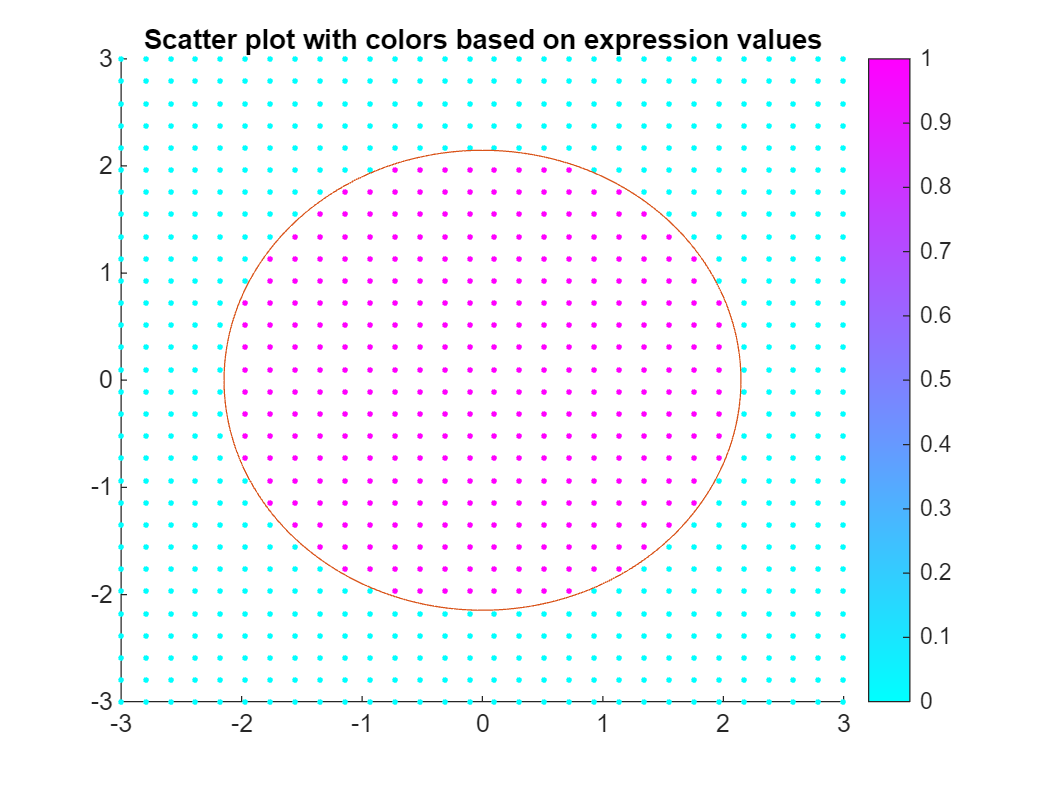

binaryValues = zeros(size(LHS_values)); 
threshold = 0.1; 
binaryValues(LHS_values>=threshold) = 1; 

%plotting 
scatterUsingValues(X,Y,binaryValues); 
hold on 
fimplicit(G_eval==threshold,[-3,3])
hold off

## Neural networks

Let's see how a neuron divides the space 

% create_simple_dnn
load net.mat

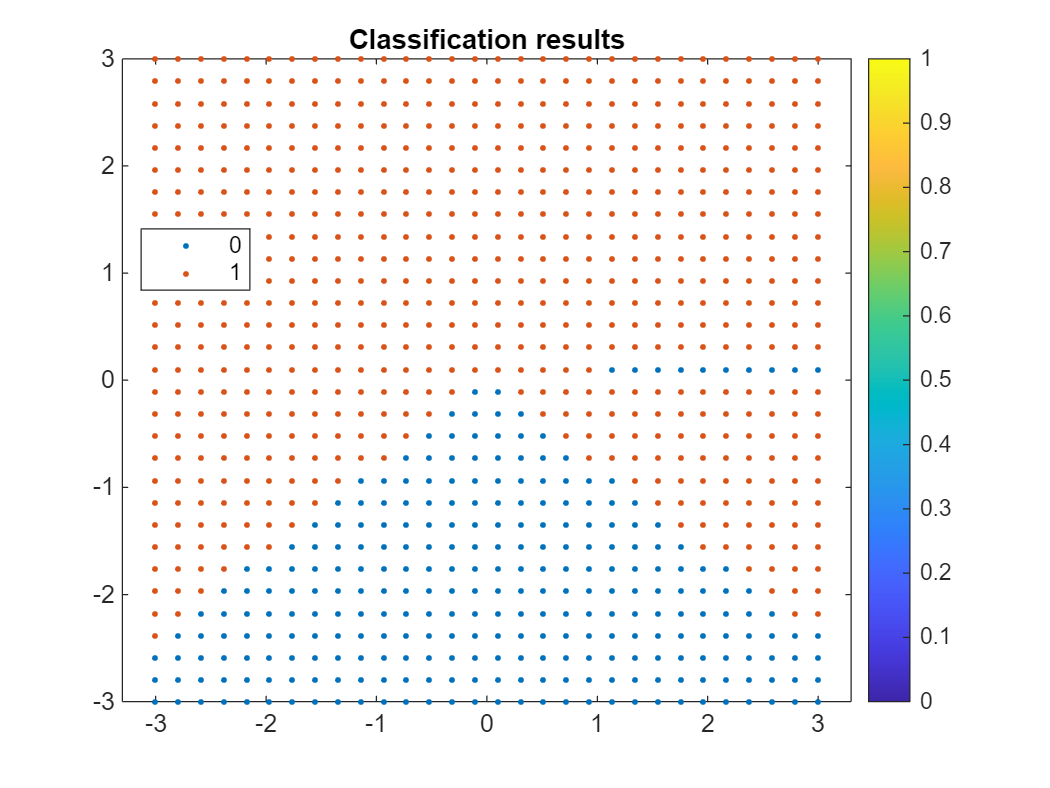

% Evaluate the network on the grid points
gridPoints = [X, Y];
% Since the output layer is a softmax layer, the predictions will be probabilities
% Get the class with the highest probability
c = predict(net, gridPoints);
g = zeros(size(c,1),1); 
g(c(:,1)>c(:,2)) = 0; 
g(c(:,1)<=c(:,2)) = 1; 
g = categorical(g); 

% Create the scatter plot
figure;
gscatter(gridPoints(:,1), gridPoints(:,2),g)
colorbar

title('Classification results');